# **Matlab案例代码解析**

## 2. 典型绘图案例

### 2.6 特殊绘图

#### 2.6.7 目标沿指定轨迹运动

颜值即正义；

**颜色模板参考：**[**60套优雅的颜色模板**](https://zhuanlan.zhihu.com/p/444970597)

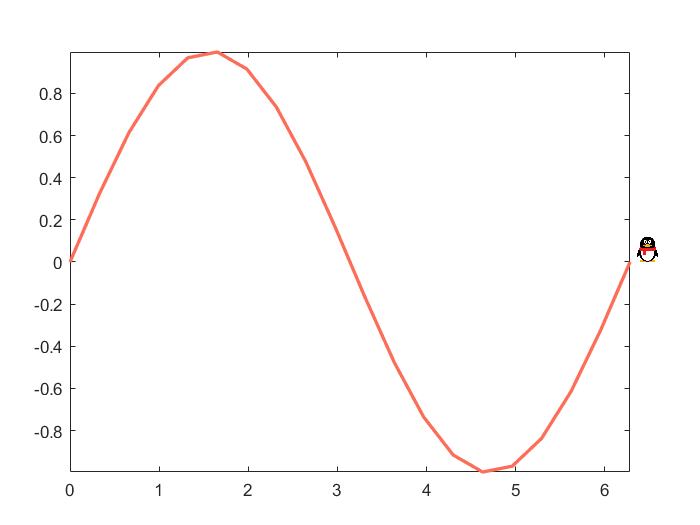

clear;clc;close all;
% 获取到颜色
[all_themes, all_colors] = GetColors(); 
% 生成轨迹
x = linspace(0, 2*pi, 20);
y = sin(x);
minX = min(x);
maxX = max(x);
minY = min(y);
maxY = max(y);
% 在特定位置绘制轨迹图
h1 = axes('position', [0.1, 0.1, 0.8, 0.8]);
plot(x, y, 'Color', all_colors(1, :), 'LineWidth', 2);
% 设置显示范围
xlim([minX, maxX]);
ylim([minY, maxY]);
% 图片尺寸
sizeQQ = 0.05;
posX = 0.1;
poxY = 0.85;
% 图像的位置
h2 = axes('position', [posX poxY sizeQQ sizeQQ]);
% 显示图片
imshow('data\qq.bmp');
for i = 1 : length(x)
    % 计算图片的位置
    posX = (x(i) - minX) / (maxX - minX) * 0.8 + 0.1;
    posY = (y(i) - minY) / (maxY - minY) * 0.8 + 0.1;
    % 删除之前的图片
    delete(h2);
    % 在新的位置显示
    h2 = axes('position', [posX posY sizeQQ sizeQQ]); 
    imshow('data\qq.bmp');
    % 暂停以显示动态过程
    pause(0.1);
end